**The Comparisons of temporal changes between WT cells and the cells with a perturbed parameter, after acute depletion of Xrn1.**

**For Figure 4d, e, and S7.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

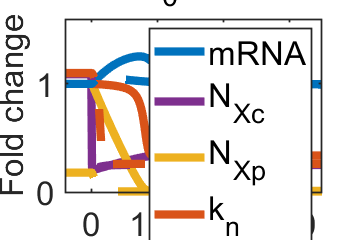

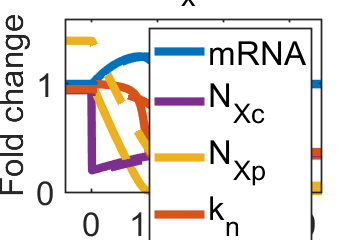

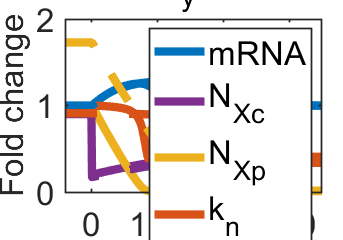

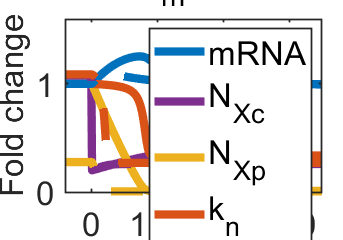

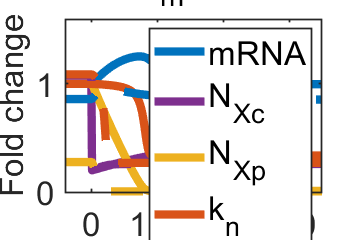

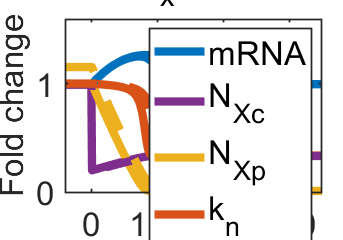

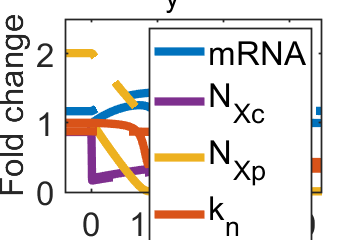

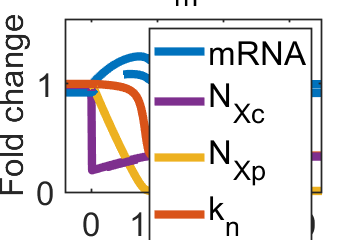

para0=[para_opt,5.8262];
%para:[k0  Kx  Ky  Km  am  ax  ay  bm  bx  Xt   Yt Kv]

% Symbolic solutions
load ../Solve_values/Solve_values.mat
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];

%%% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

% The degree of the perturbations for each paramters
pertb=[1.2,5, 5, 1.2,1.2,100,1.2,2, 1.2,0.9,0.5,1.1];
%     [k0  Kx Ky Km  am  ax  ay  bm bx  Xt  Yt  Kv]

names=["k012","Kx5","Ky5","Km12","am12","ax100","ay12","bm2","bx12","Xt09","Yt05","Kv11"];
names_tex=["k_0","K_x","K_y","K_m","\alpha_m","\alpha_x","\alpha_y","\beta_m","\beta_x","N_{Xt}","N_{Yt}","K_v"];
y_max=[1.6,1.6,2,1.6,1.6,1.6,2.5,1.6,2.5,1.6,1.6,1.6];


for i=1:12

    fig=figure;
    set(fig,'Position',[300 100 1000 700]);
    ax1=axes('position', [0.19 0.2 0.75 0.72]);

    % Simulations for WT cells
    para1=para0;
    [kn_wt1,kn_tot1,y_wt1,y_tot1]=Xcdeplete_noFC(para1,syms_solve);
    %y:[mn mc Xn Xc Xp Yn Yp]

    temp_m=(y_tot1(:,1)+y_tot1(:,2))./(y_wt1(:,1)+y_wt1(:,2));
    temp_Xc=y_tot1(:,4)./y_wt1(:,4);
    temp_Xp=y_tot1(:,5)./y_wt1(:,5);
    temp_kn=kn_tot1./kn_wt1;

    temp_m=[ones(1,100),temp_m'];
    temp_Xc=[ones(1,100),temp_Xc'];
    temp_Xp=[ones(1,100),temp_Xp'];
    temp_kn=[ones(1,100),temp_kn];
    temp2=[-99:1000];

    p1=plot(temp2,temp_m, ...
        'DisplayName',"mRNA", ...
        "Color",colors(1),...
        "LineWidth",5);
    hold on
    p2=plot(temp2,temp_Xc, ...
        'DisplayName',"N_{Xc}", ...
        "Color",colors(4),...
        "LineWidth",5);
    hold on
    p3=plot(temp2,temp_Xp, ...
        'DisplayName',"N_{Xp}", ...
        "Color",colors(3),...
        "LineWidth",5);
    hold on
    p4=plot(temp2,temp_kn, ...
        'DisplayName',"k_n", ...
        "Color",colors(2),...
        "LineWidth",5);

    hold on

    % Simulations for perturbed cells
    para1=para0;
    para1(i)=para0(i)*pertb(i); %perturbation
    [kn_wt2,kn_tot2,y_wt2,y_tot2]=Xcdeplete_noFC(para1,syms_solve);
    %y:[mn mc Xn Xc Xp Yn Yp]

    % All values in perturbed cells are normalized to those in WT cells
    temp_m=(y_tot2(:,1)+y_tot2(:,2))./(y_wt1(:,1)+y_wt1(:,2));
    temp_Xc=y_tot2(:,4)./y_wt1(:,4);
    temp_Xp=y_tot2(:,5)./y_wt1(:,5);
    temp_kn=kn_tot2./kn_wt1;

    bf_dep_m=(y_wt2(1)+y_wt2(2))./(y_wt1(1)+y_wt1(2));
    bf_dep_Xc=y_wt2(4)./y_wt1(:,4);
    bf_dep_Xp=y_wt2(5)./y_wt1(:,5);
    bf_dep_kn=kn_wt2./kn_wt1;

    temp_m=[ones(1,100)*bf_dep_m,temp_m'];
    temp_Xc=[ones(1,100)*bf_dep_Xc,temp_Xc'];
    temp_Xp=[ones(1,100)*bf_dep_Xp,temp_Xp'];
    temp_kn=[ones(1,100)*bf_dep_kn,temp_kn];
    temp2=[-99:1000];

    plot(temp2,temp_m,'--', ...
        'DisplayName',"mRNA", ...
        "Color",colors(1),...
        "LineWidth",5);
    hold on
    plot(temp2,temp_Xc-0.01,'--',  ...
        'DisplayName',"N_{Xc}", ...
        "Color",colors(4),...
        "LineWidth",5);
    hold on
    plot(temp2,temp_Xp,'--',  ...
        'DisplayName',"N_{Xp}", ...
        "Color",colors(3),...
        "LineWidth",5);
    hold on
    plot(temp2,temp_kn,'--',  ...
        'DisplayName',"k_n", ...
        "Color",colors(2),...
        "LineWidth",5);
    hold off

    xlim([-40,350])
    ylim([0,y_max(i)])
    set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
    set(gca,'FontSize',20)
    set(gca,'Layer','top')
    box(gca,'on')
    legend([p1 p2 p3 p4],"FontSize",20)
    title( strcat(names_tex(i),'*',num2str(pertb(i))));
    xlabel('Time (min)','interpreter','tex','FontSize',20);
    ylabel('Fold change','interpreter','tex','FontSize',20);

    
end

function dydt = diffun(y,para)
%%% Differential equations of the system

%y:[mn mc Xn Xc Xp Yn Yp]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);

%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt Kv]

k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);
Kv=para(12);


dydt = zeros(7,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt]

Vn=2.8;%fL
Vc=37.2;%fL

kn=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

dydt(1)=kn-am*(Yn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-ax*Xn;
dydt(4)=ax*Xn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=ay*Yn-kn;

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




function [kn_wt,kn_tot,y_wt,y_tot]=Xcdeplete_noFC(para0,syms_solve)
%%% The function calculating the values of molecules.

%Numerically solve the values of molecules in WT cells
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=[para0(1:11),2.8,37.2,para0(12)];
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt Kv]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para0(7)/para0(5),37.2*para0(9)/para0(8)];% mn mc

y_wt=[temp2,temp1];


%paramters
k0=para0(1);
Kx=para0(2);
Ky=para0(3);
Km=para0(4);
%am=para0(5);
%ax=para0(6);
%ay=para0(7);
%bm=para0(8);
%bx=para0(9);
%Xt=para0(10);
%Yt=para0(11);
Kv=para0(12);
mn=y_wt(1);
%mc=y_wt(2);
%Xn=y_wt(3);
%Xc=y_wt(4);
Xp=y_wt(5);
%Yn=y_wt(6);
Yp=y_wt(7);
Vn=2.8;%fL
%Vc=37.2;%fL

kn_wt=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);

y_ini=y_wt;
y_ini(3)=y_ini(3);
y_ini(4)=y_ini(4)*0.2;%Deplete 80% of Xc
y_ini(5)=y_ini(5);

%Calculate the values of molecules after depletion
tspan=[1:1:1000];
[~,y_tot]=ode15s(@(t,y)diffun(y,para0),tspan,y_ini);

%Calculate the kn after depletion
kn_tot=zeros(1,length(tspan));
for i=1:length(tspan)
    mn=y_tot(i,1);
    %mc=y_tot(i,2);
    %Xn=y_tot(i,3);
    %Xc=y_tot(i,4);
    Xp=y_tot(i,5);
    %Yn=y_tot(i,6);
    Yp=y_tot(i,7);
    kn_tot(i)=(k0*Vn/(Vn+Kv))*(Xp/(Xp+Kx*Vn))*Vn*Km/(Vn*Km+mn)*Yp/(Yp+Ky*Vn);
end


end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%